# Capstone Exercise ROS Solution

Insert the Vision Module below

q_init = [pi,-pi/3,-pi/2,-pi/2,pi/4,0]';
 
%q_init = [0,-pi/2,0,-pi/2,0,0]'; 
resetme(q_init); 
% while true
% 
% end

function resetme(q_desired)
q=GetJointStates(); 

while(any(abs(q-q_desired)>0.1))
SendJointSpeeds(q_desired-q);

q=GetJointStates(); 
end

end

Put the Robotics solution below 

% % 

ur_model="universalUR3e"; 
StartTutorialApplication('Simulation', 'Model', ur_model, 'controller','velocity'); 
StartTutorialApplication('Trajectory', 'num_points',500); 
StartTutorialApplication('safety_nodes'); 


%% ---- Parameters ----
kx = 0.3;
kz = 0.3;
kt = 0.3;

dead = 0.03;

v_max_lin = 0.25;   % [m/s]
v_max_ang = 1.00;   % [rad/s]

q_dot_limits = ones(6,1);  % replace with real joint limits if desired

sigma_thresh = 0.02;     % singularity threshold on sigma_min(Jv)
lambda_max   = 0.02;       % max damping near singularity

%% ---- Robot model ----
ur_model = "universalUR3e";
ur = loadrobot(ur_model, DataFormat="column", Gravity=[0,0,-9.81]);
ur_home = [0,-pi/2,0,-pi/2,0,0]';

%% ---- Workspace radius from home pose (shoulder_link frame) ----
T_home = getTransform(ur, ur_home, "tool0", "shoulder_link");
R_home = norm(tform2trvec(T_home));

R_safe = 0.5 * R_home;     % peak speed radius

VisualizeWorkspace(R_home);

%% ---- Rate control ----
r = rateControl(80);

cam = webcam(); 
minConf=0.7; 
tracked_fruit="apple"; 
det = yolov8ObjectDetector2('yolov8s');

This can take several minutes to download...
Done.



video_scale=0.2; 
vel_scaling = 0.2;

start=tic

start = uint64
1777815248761471

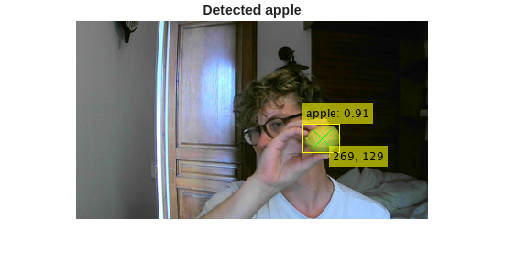

  118.1000  104.9000



   39.4000   32.2000



  101.9000  101.0000



   39.4000   31.6000



  123.8000  111.5000



   40.0000   32.2000



  152.3000  110.3000



   41.8000   32.2000



  162.8000  110.0000



   42.4000   31.6000



  173.6000  110.3000



   42.4000   32.2000



  178.4000  110.3000



   42.4000   32.2000



  180.8000  112.1000



   42.4000   32.2000



  197.6000  112.7000



   42.4000   32.2000



  208.4000  115.7000



   42.4000   32.2000



  221.6000  122.3000



   43.6000   33.4000



  225.5000  125.9000



   41.8000   32.2000



  260.3000  131.0000



   40.6000   31.6000



  268.7000  129.2000



   40.6000   31.6000



fig = figure; 
count = 0; 
while toc(start)<5

[centroid, BB_size] = CapstoneCV(cam, det, minConf,tracked_fruit,video_scale,false); 
disp(centroid)
disp(BB_size)
count = count+1; 
end

fps=count/5; 



centroid_prev=[]; 
BB_prev=[]; 


[centroid, BB_size] = CapstoneCV(cam, det, minConf,tracked_fruit,video_scale,false); 
delta_centroid = centroid-centroid_prev; 
delta_BB = BB_size-BB_prev; 

centroid_prev = centroid; 
BB_prev = BB_size;


vel_raw = [centroid',delta_BB'*delta_BB]; 
vel = vel_raw * vel_scaling 



try
    while true
        %% --- Joint state ---
        q = GetJointStates();

        %% --- Tool pose in base (for frame mapping) ---
        T_base_tool = getTransform(ur, q, "tool0", "base_link");
        Rbt = T_base_tool(1:3,1:3);
        pbt = tform2trvec(T_base_tool).';  % 3x1

        %% --- Teleop error: [ex, ez, escale] ---
        e = GetTeleoperation();
        e = e(:);
        e_x = e(1); e_z = e(2); e_scale = e(3);

        %% --- Workspace radius in shoulder_link ---
        T_ws  = getTransform(ur, q, "tool0", "shoulder_link");
        r_cur = norm(tform2trvec(T_ws));

        % Speed scaling:
        %   s = 1 at r = R_safe
        %   s -> 0 as r -> 0 or r -> R_home
        %   s = 0 for r >= R_home (hard stop)
        % --- Donut scaling: slow inside, fast mid, slow outside ---
        r0      = 0.00 * R_home;      % inner hard stop radius (often 0)
        band_width = 0.25 * R_home;     % Gesamtbreite der Vollspeed-Zone
        r_peak1 = R_safe - band_width/2;
        r_peak2 = R_safe + band_width/2;    % end of full-speed band
        r1      = R_home;             % outer hard stop
        
        
        if r_cur >= r1
            s = 0;
        
        elseif r_cur >= r_peak2
            % smooth falloff from 1 -> 0 (r_peak2 -> r1)
            x = (r_cur - r_peak2) / (r1 - r_peak2);   % [0,1]
            s = 0.5 * (1 + cos(pi * x));          % 1 -> 0
        
        elseif r_cur >= r_peak1
            % flat top
            s = 1;
        
        else
            % smooth ramp from 0 -> 1 (r0 -> r_peak1)
            if r_cur <= r0
                s = 0;
            else
                x = (r_cur - r0) / (r_peak1 - r0);    % [0,1]
                s = 0.5 * (1 - cos(pi * x));      % 0 -> 1
            end
        end

        %% --- Deadband + scaling ---
        if abs(e_x)     < dead, e_x = 0; end
        if abs(e_z)     < dead, e_z = 0; end
        if abs(e_scale) < dead, e_scale = 0; end

        e_x     = e_x     * s;
        e_z     = e_z     * s;
        e_scale = e_scale * s;

        %% --- Desired twist in base ---
        v_base = zeros(6,1);
        v_base(1) = kx * e_x;
        v_base(3) = kz * e_z;

        v_tool = zeros(6,1);
        v_tool(3) = kt * e_scale;  % tool Z (linear)

        % Tool twist -> base twist (adjoint)
        v_tool_lin_b = Rbt * v_tool(1:3) + cross(pbt, Rbt * v_tool(4:6));
        v_tool_ang_b = Rbt * v_tool(4:6);
        v_cmd = v_base + [v_tool_lin_b; v_tool_ang_b];

        %% --- Cartesian saturation (norm-based) ---
        v_lin = v_cmd(1:3);
        v_ang = v_cmd(4:6);

        nlin = norm(v_lin);
        nang = norm(v_ang);

        if nlin > v_max_lin && nlin > 0
            v_lin = v_lin * (v_max_lin / nlin);
        end
        if nang > v_max_ang && nang > 0
            v_ang = v_ang * (v_max_ang / nang);
        end

        v_cmd = [v_lin; v_ang];

        %% --- Jacobian and DLS IK ---
        J = geometricJacobian(ur, q, "tool0");
        J = [J(4:6,:); J(1:3,:)];   % [linear; angular]

        Jv = J(1:3,:);
        sigma_min = min(svd(Jv));

        if sigma_min < sigma_thresh
            lambda = lambda_max * (1 - min(1, sigma_min/sigma_thresh));
        else
            lambda = 0;
        end

        q_dot = J' / (J*J' + (lambda^2)*eye(6)) * v_cmd;


        % --- Joint velocity saturation (preserve direction) ---
        ratio = abs(q_dot) ./ q_dot_limits;
        s_q = max(ratio);              % worst-case saturation ratio
        
        if s_q > 1
            q_dot = q_dot / s_q;       % scale down uniformly
        end
        
        % optional: tiny numerical safety clip (should rarely do anything now)
        q_dot = min(max(q_dot, -q_dot_limits), q_dot_limits);


        %% --- Command + visualize ---
        SendJointSpeeds(q_dot);

        JointStatesToRviz(q, ur_model, [], ...
            "Ellipsoid", true, "SendJointStates", false, "EllipsoidResolution", 10);

        waitfor(r);
    end
catch ME
    try
        SendJointSpeeds(zeros(6,1));
    catch
    end
    rethrow(ME);
end

